## HO-SVD

clear;
clc;

format short g;

% Set seed
rng(197);

**Continuous Complex System**

We consider the 2-parameter complex system, where $f(x_1,x_2)=\Lambda(x_1,x_2)(e \times sin(8x_1) + 5 sin(3x_2))$ when $x_1 < x_2$ and $f(x_1,x_2)=(1-\Lambda(x_1,x_2))(e \times sin(8x_1) + 5 sin(3x_2))$ when $x_1 \geq x_2$. Furthermore, $\Lambda(x_1,x_2)$ is an exponential smoothing term, which smooths the transition, where $x_1 \sim x_2$.

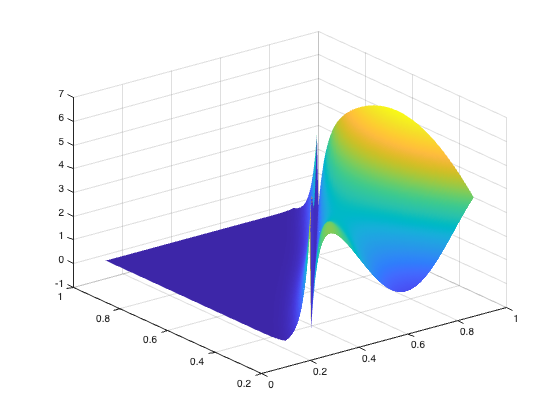

%% Create Space
load Space_Slanted_Border_Function.mat;

surf(X,Y,Space,'EdgeColor','none')

**Default parameters**

In our experiments,

- We set the default per time stamp sampling budget $B^t$ to **0.02%** of the volume of the space.

- The target rank for HO-SVD is set to **25%** of the size of the parameter space.

- The default exploration probability for BFF-RS and GFF-RS is set to **0.15**.

- All experiments were run for **50** times and averages are reported.

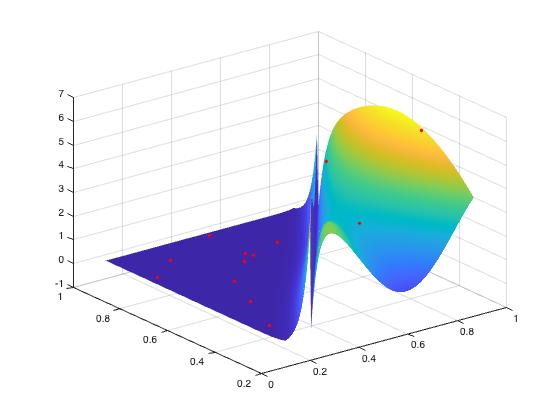

dimX = size(X,1);
dimY = size(Y,1);
volume = dimX * dimY;
budget = ceil(0.0002 * volume);

samples = randi(dimX,budget,2);

x = zeros(1,budget);
y = zeros(1,budget);
s = zeros(1,budget);
for i = 1:budget
    x(i) = X(samples(i,1),samples(i,2));
    y(i) = Y(samples(i,1),samples(i,2));
    s(i) = Space(samples(i,1),samples(i,2));
end

surf(X,Y,Space,'EdgeColor','none')
hold on
plot3(x,y,s,'.r','markersize',10)
hold off

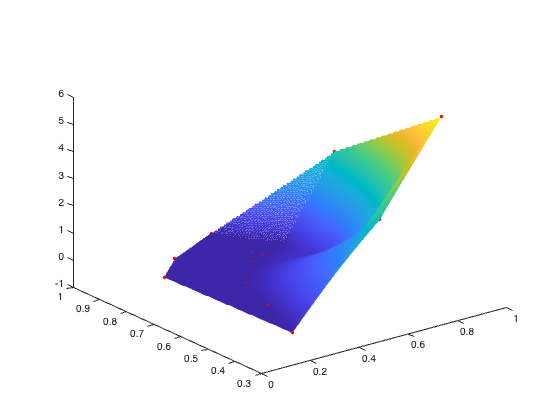

z = griddata(x,y,s,X,Y,"natural");
plot3(x,y,s,'.r','markersize',10)
hold on
mesh(X,Y,z)
hold off

T = sptensor(samples,s',[dimX dimY]);


% D = {x,y,s};
% A = cat(3,D{:});
% T = tensor(A);

% [core,U] = tensor_hosvd(Space);
eps = 0.0002; %Tolerance
%% HOSVD estimation
T_full = full(T);  % Convert T to a (dense) tensor
T_doub = double(T_full);
decom = hosvd(T_full,2*sqrt(eps));

Computing HOSVD...
Size of core: 4 x 4
||X-T||/||X|| = 0.00207692 <=0.028284 (tol)



%Factor matrices (U,V,W) and core tensor
core=decom.core;
G=double(core);
U=decom.U{1};
V=decom.U{2};
% W=decom.U{3};


%% SAMPLE SELECTION STRATEGIES

decom_doub = double(decom);
decom_tens = full(decom);
% decom_doub = double(full(decom));
% tf = isequal(decom_doub1,decom_doub2);


% params = decom_tens; T_full
fit = norm(decom_tens - T_full) / norm(T_full);



subs = decom_tens - T_full;
subs_abs = abs(double(subs));

total_sum = sum(subs_abs, "all");

% Degree of fit

% checks = zeros(1,budget);
fittings = zeros(1,budget);
for i = 1:budget
    % checks(i) = subs_abs(samples(i,1),samples(i,2));
    fittings(i) = subs_abs(samples(i,1),samples(i,2)) / total_sum;
end


% N = sqrt(sum(T_doub.^2, 'all'));
% C = subs ./ N;


% BAD FIT FIRST

% Criticality

epsilon = 2.2251e-308;
criticality_BFF = zeros(1,budget);
for i = 1:budget
    criticality_BFF(i) = 1 / (fittings(i)+epsilon);
end

% summ = 0;
inv = zeros(1,budget);
for i = 1:budget
    inv(i) = 1 / (fittings(i)+epsilon);
end

% Sampling weight

weight_mat = zeros(size(Space));
% Check also `find` and `ismember`
for ii = 1:size(Space,1)
    for jj = 1:size(Space,2)
        % ii -> rows, jj -> columns
        % If it is not a pivot
        if sum(ismember(samples,[ii jj],'rows')) ~= 1
            weight = 0;
            for i = 1:budget
                if samples(i,1) == ii || samples(i,2) == jj
                    weight = weight + criticality_BFF(i);
                end
            end
        else
            weight = 0;
        end
        weight_mat(ii,jj) = weight;
    end
end

% Sampling probability

total_sum = sum(weight_mat, "all");  % Inf


surf(X,Y,weight_mat,'EdgeColor','none')






% GOOD FIT FIRST

% BFF WITH RANDOM SAMPLING

% GFF WITH RANDOM SAMPLING

% HYBRID SAMPLING STRATEGY


for i = 1:samples
    disp(weight_mat(samples(i,1),samples(i,2)));
end

% norm(C(i,j))









% D = {X,Y,Space};
% A = cat(3,D{:});
% T = tensor(A);

load('dataset/trafficdb/traffic_patches.mat');
A2 = double(imgdb{100});
T2 = tensor(A2);



str=load('tensor_test.mat','tensor');
str_xyz=load('xyztensor.mat','tensor_xyz');

a=str.tensor; %Microseismic Data
b=str_xyz.tensor_xyz; %XYZ Microseismic Data
X2=tensor(b);
X_doub=double(X2);
xs=size(X_doub);

eps = 0.0002; %Tolerance
%% HOSVD estimation
T2 = hosvd(X2,2*sqrt(eps));

Computing HOSVD...
Size of core: 181 x 12 x 31
||X-T||/||X|| = 0.0222021 <=0.028284 (tol)

